# cpaPlot

CPA plotting script for individual CPAs with toggles for each plotting set, and procion to save figures.

clear all
tog.VOI = 'Amundsen-AAA1-28Aug19-A';
par = setPars;
load(fullfile(par.procPath,tog.VOI));

proc.plotSpec = 'yes';
proc.plotTracking = 'yes';
proc.plotGeo = 'yes';
proc.plotWindows = 'yes';
proc.plotLobing = 'yes';
proc.plotHeat = 'no';
proc.saveFigs = '0'; 
tog.saveFigs = proc.saveFigs;

## Plot spectrograms

    switch proc.plotSpec
        case 'no'
        case 'yes'
            plotSpec(par, tog, TimeVector, S, SL, proc, fSpectra);
    end

## Plot geospatial figures

    switch proc.plotGeo
        case 'no'
        case 'yes'
            plotGeo(SPL, par, tog, CPA, array2, array1);
    end

## Plot noise windows figures

    switch proc.plotWindows
        case 'no'
        case 'yes'
            plotWindows(SPL, par, RLship, timeCPA, tog, TimeVector, SL, proc, timeVector);
    end

## Plot tracking figures

    switch proc.plotTracking
        case 'no'
        case 'yes'
            plotSpecWScatter(par, tog, TimeVector, Sz, proc, Fz, Tonal)
    end

## Plot narrowband lobing figures

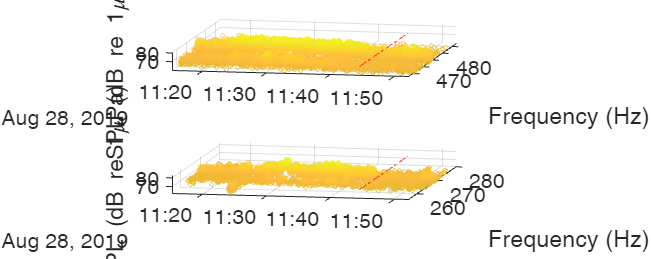

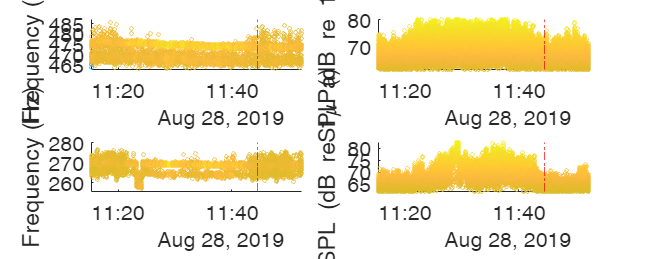

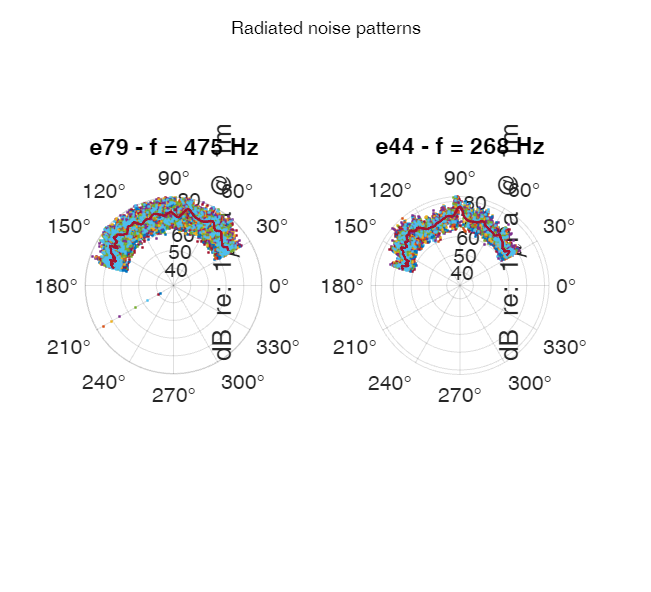

    switch proc.plotLobing
        case 'no'
        case 'yes'
            plotNbLobing(Tonal, Fz, SPL, par, proc, timeCPA, tog, timeVector)
    end